time2 = DYOErunsaani217065801709430.AnalogChannels; 
signal2 = DYOErunsaani217065801709430.VarName5; 
k = [time2,signal2]; 

% determine sampling frequency
Fs = 1 / mean(diff(time2));  % Sampling frequency in Hz



% analyze frequency components
Y = fft(signal2);
L = length(signal2);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

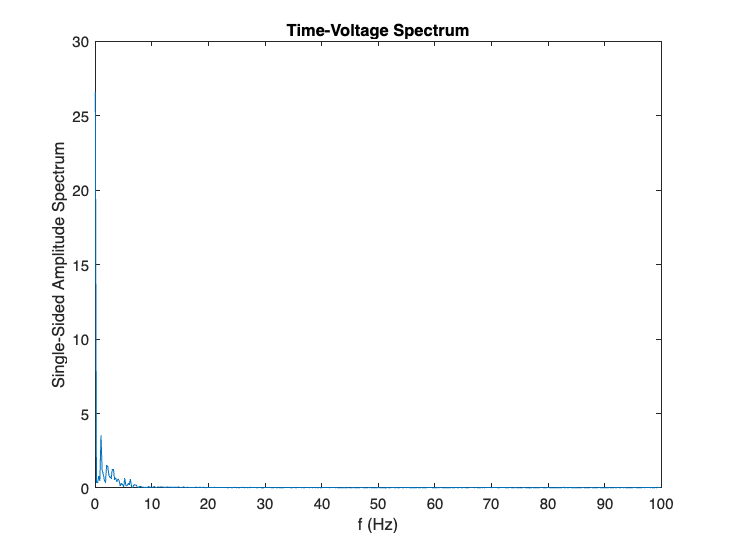

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f, P1);
title('Time-Voltage Spectrum');
xlabel('f (Hz)');
ylabel('Single-Sided Amplitude Spectrum');

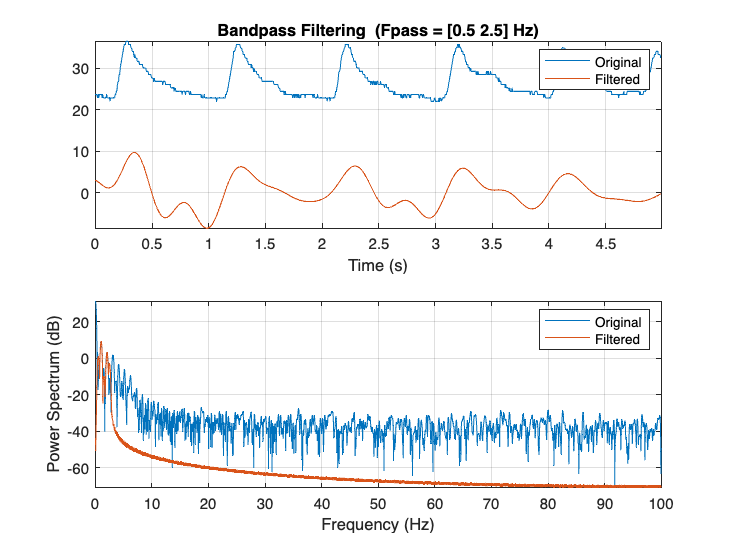

bandpass(signal2,[0.5 2.5],Fs)